# Brain Tumor Segmentation using the custom threshold tecnique proposed by Umit Ilhana, Ahmet Ilhana

## 1 - Loading the MRI

In this first section, we load the MRI image aimed for tumor segmentation, along with the accompanying label that contains the ground truth segmentation of the tumor.

clear all
close all
clc

addpath('utilities');
addpath('tests');


% Setting that you can change
dimension4 =4;
numberOfImg = 82;

file_name = sprintf('BRATS_%03d.nii.gz', numberOfImg);
full_path_tr = fullfile('dataset/imagesTr/', file_name);
full_path_label = fullfile('dataset/labelsTr/', file_name);

[brainMRI, brainMRInormalized] = openMRI(full_path_tr);
brainMRI = brainMRI(:, :, :, dimension4);
brainMRInormalized = brainMRInormalized(:, :, :, dimension4);

[labelMRI, labelMRInormalized] = openMRI(full_path_label);

## 2 - Localize where the tumor is (only for test purposes)

For better comprehension and testing, we localize the tumor's location using the label. It's important to note that this section of the code will not be employed for the actual segmentation. This is useful to calculate in an automatic way the middle slice where the tumor is located.

[nonZeroX, nonZeroY, nonZeroZ] = ind2sub(size(labelMRI), find(labelMRI));

xmin = min(nonZeroX);
xmax = max(nonZeroX);
ymin = min(nonZeroY);
ymax = max(nonZeroY);
zmin = min(nonZeroZ);
zmax = max(nonZeroZ);

fprintf("Tumor is located between the following boundaries:\n");

Tumor is located between the following boundaries:


fprintf('X Range -> [%d, %d]\n', xmin, xmax);

X Range -> [60, 117]


fprintf('Y Range -> [%d, %d]\n', ymin, ymax);

Y Range -> [74, 155]


fprintf('Z Range -> [%d, %d]\n', zmin, zmax);

Z Range -> [35, 101]


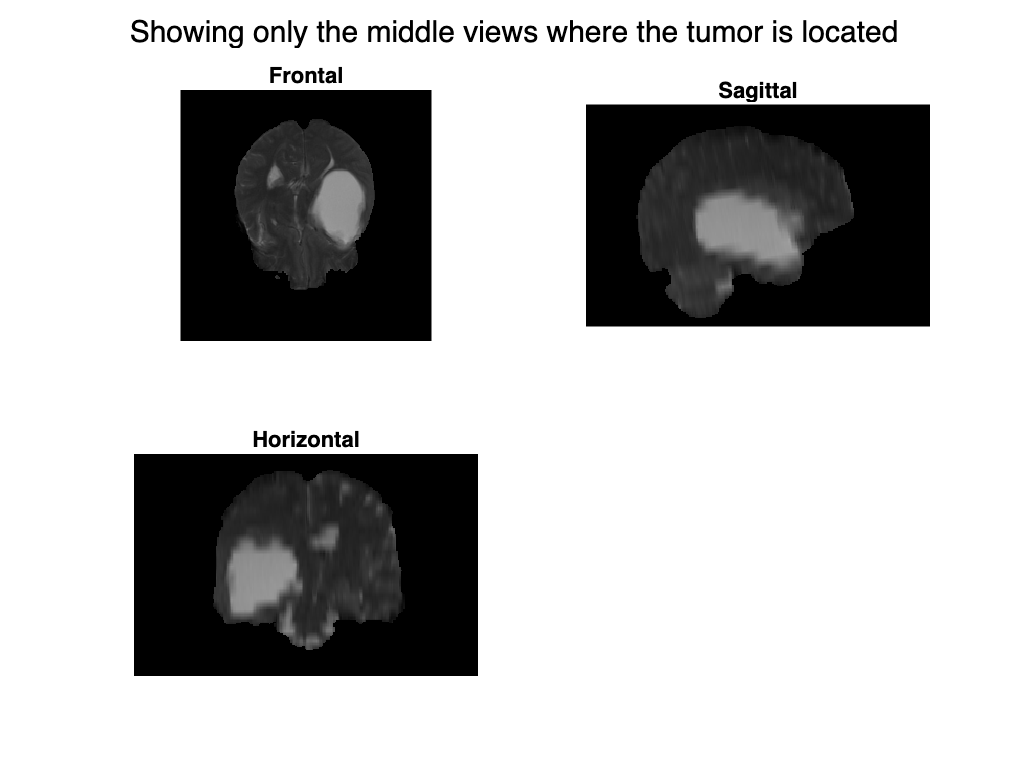


xMiddle = round((xmin + xmax)/2);
yMiddle = round((ymin + ymax)/2);
zMiddle = round((zmin + zmax)/2);
show2D(brainMRInormalized, xMiddle, yMiddle, zMiddle);
sgtitle("Showing only the middle views where the tumor is located")

## 3 - Visualize the tumor in 3D using volshow()

The `volshow` function generates a Volume object showcasing the 3D volume. This object allows interactive manipulation, enabling rotation and zooming in and out using mouse controls. Here we show the brain and also the ground-truth label of the tumor: 

volshow(brainMRI);
disp("")
volshow(labelMRI);

## 4.a - Preprocessing: adjust the contrast of the image

To enhance the visibility of the tumor in the image, an image stretching function is employed. The `imadjustn` function proves useful in this context. The determination of lower and upper bounds is guided by the information derived from the histogram of the image.

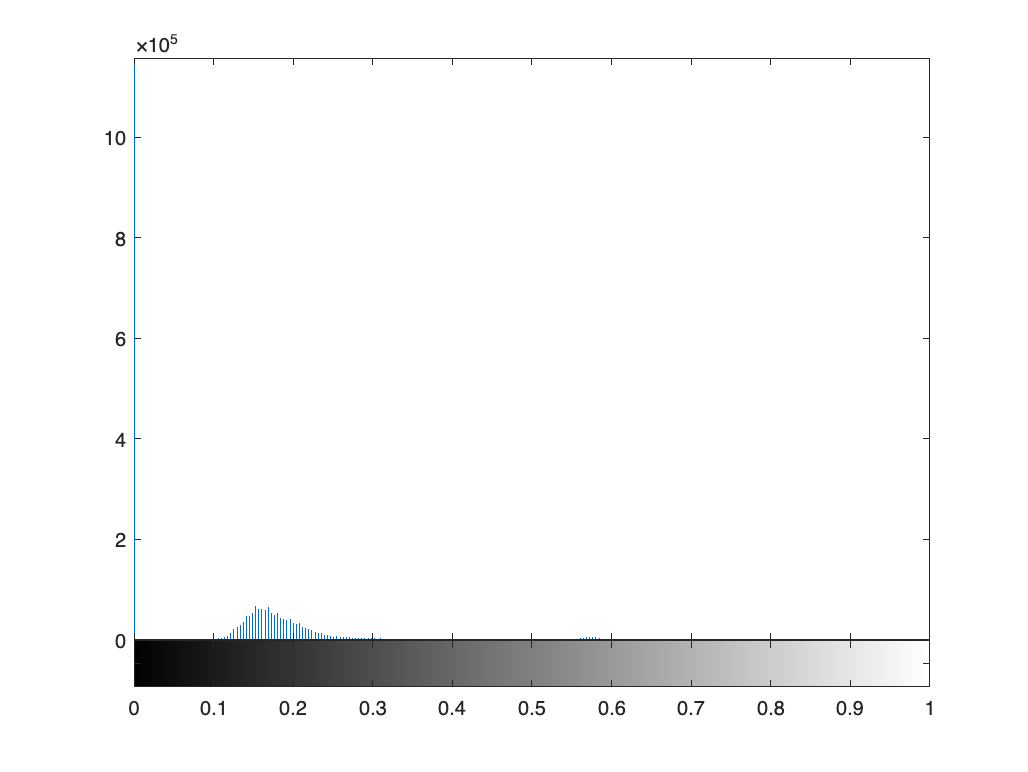

figure
imhist(reshape(brainMRInormalized, [], 1));

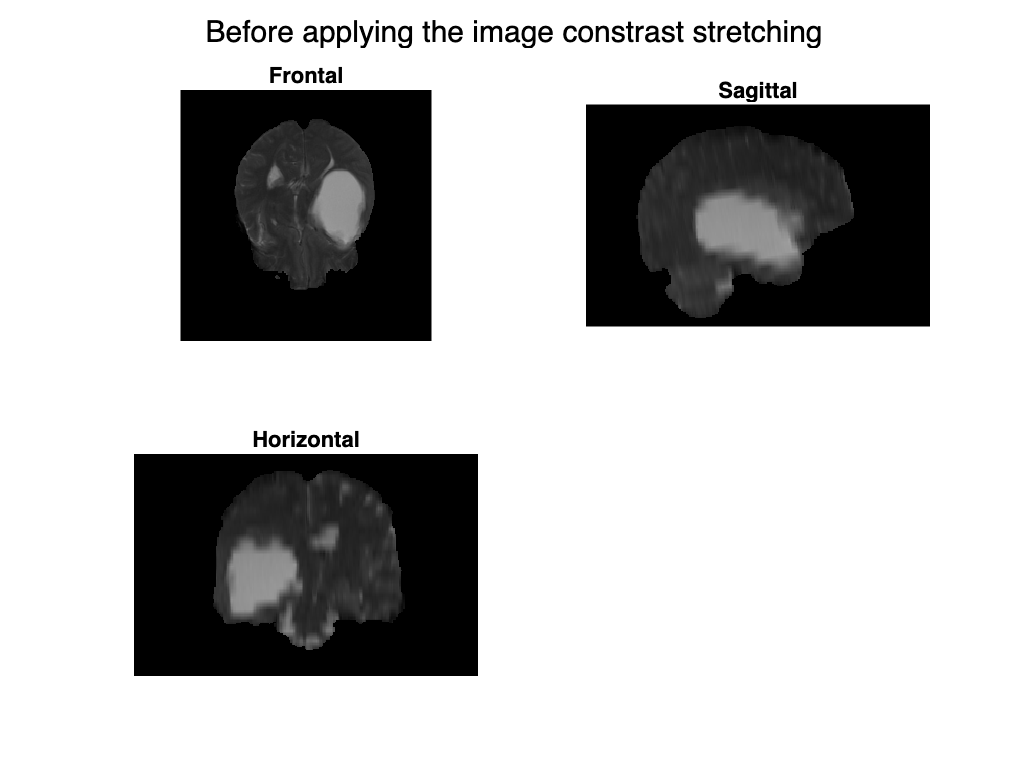



brainMRIStrectched = imadjustn(brainMRInormalized, [0 0.7], [0 1]);
show2D(brainMRInormalized, xMiddle, yMiddle, zMiddle);
sgtitle("Before applying the image constrast stretching")

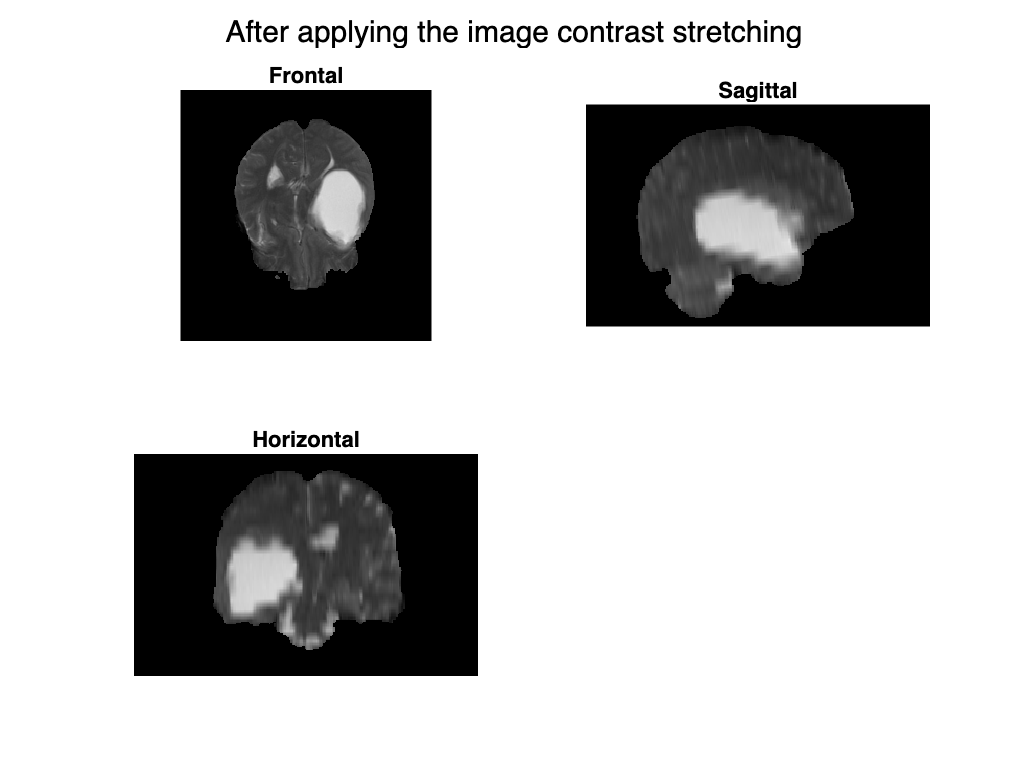

show2D(brainMRIStrectched, xMiddle, yMiddle, zMiddle);
sgtitle("After applying the image contrast stretching")

## 4.b - Other preprocessing steps tried but not successful

This stage involves two preprocessing steps that I attempted, but they turned out to be wrong intuitions. The first attempt involved sharpening the image using a Laplacian filter to enhance the contours, while the second attempt involved applying an average filter to the image.

% Laplacian sharpner filter

% kernel = fspecial3('gaussian', [5 5 5], 0.1);
% brainMRIStrectched = imfilter(brainMRIStrectched, kernel);
% 
% kernel = zeros(3, 3, 3);
% kernel(:,:,1) = [0 0 0; 0 1 0; 0 0 0];
% kernel(:,:,2) = [0 1 0; 1 -6 1; 0 1 0];
% kernel(:,:,3) = [0 0 0; 0 1 0; 0 0 0];
% filtered = imfilter(brainMRIStrectched, kernel, 'conv', 'replicate');
% brainMRIStrectched = brainMRIStrectched - filtered;
% show2D(brainMRIStrectched, xMiddle, yMiddle, zMiddle);
% sgtitle("After applying the Laplacian sharpner filter")

% Average filter
% brainMRIStrectched = imboxfilt3(brainMRIStrectched,[5 5 5]);
% show2D(brainMRIStrectched, xMiddle, yMiddle, zMiddle);
% sgtitle("After applying the average filtering")

## **5.a - Segment the tumor using the novel thresholding algorithm**

In this method proposed by Umit Ilhana, Ahmet Ilhana, sum of unique pixel values excluding zeros (black pixels) are divided by the count of unique pixel values. By this operation, the average gray value (threshold value) is calculated to convert the grayscale image to binary image.

uniquePixels = unique(brainMRIStrectched(brainMRIStrectched ~= 0));
sumUniquePixels = sum(uniquePixels);
countUniquePixels = numel(uniquePixels);
thresholdValue = sumUniquePixels / countUniquePixels;
fprintf("The thresholding value found is %.3f", thresholdValue);

The thresholding value found is 0.456

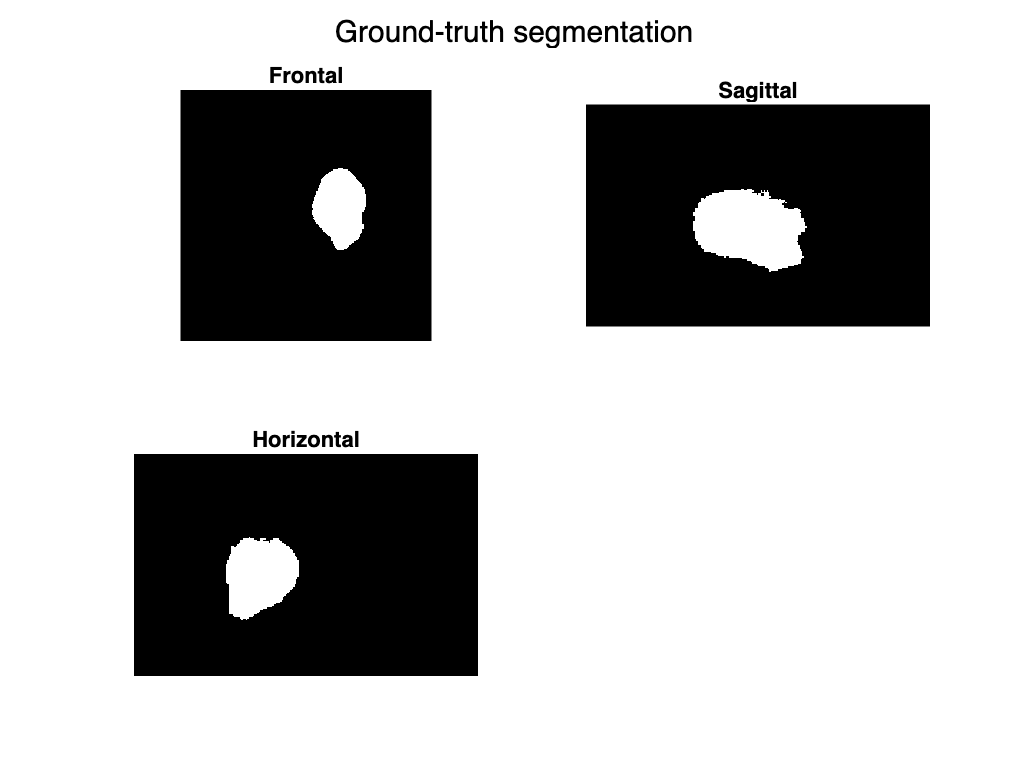


labelMRIbinarized = labelMRInormalized > 0;
show2D(labelMRIbinarized, xMiddle, yMiddle, zMiddle);
sgtitle("Ground-truth segmentation")

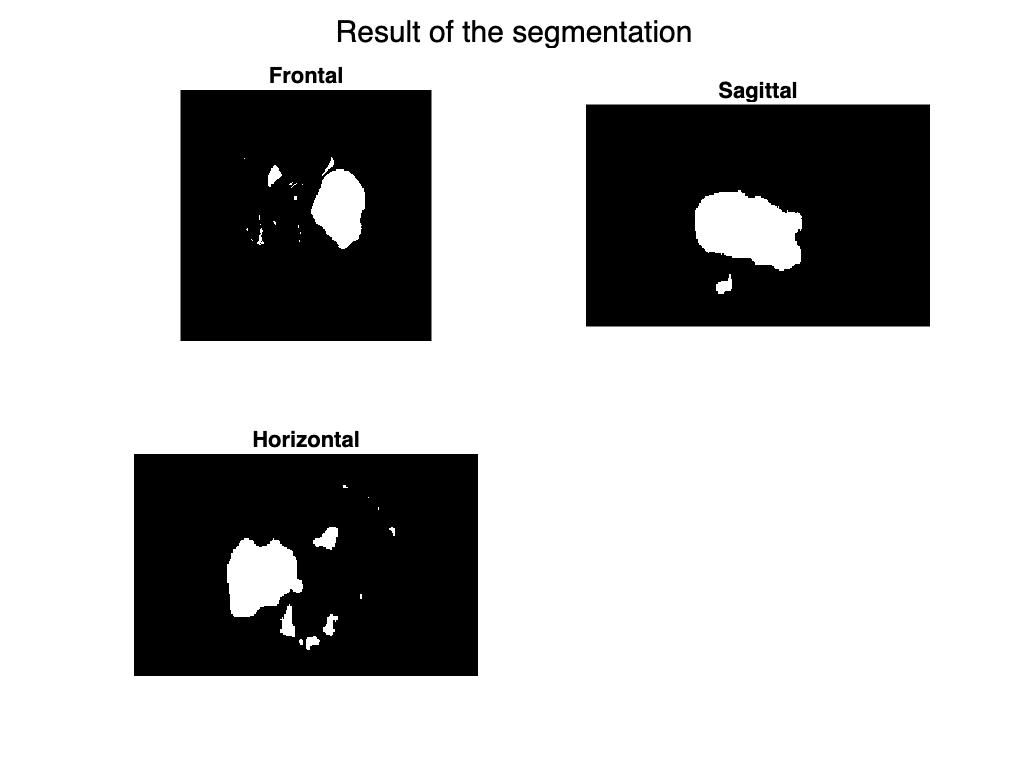


binaryBrain = brainMRIStrectched > thresholdValue;
show2D(binaryBrain, xMiddle, yMiddle, zMiddle);
sgtitle("Result of the segmentation")

## **5.b - Segment the tumor using the Otsu algorithm**

In this method, we use the Otsu method for segmenting the brain tumor just to compare another algorithm that calculate the threshold.

% labelMRIbinarized = labelMRInormalized > 0;
% show2D(labelMRIbinarized, xMiddle, yMiddle, zMiddle);
% sgtitle("Ground-truth segmentation")
% 
% binaryBrain = imbinarize(brainMRIStrectched, "global");
% show2D(binaryBrain, xMiddle, yMiddle, zMiddle);
% sgtitle("Result of the segmentation")

## **6 - Postprocessing operations: median filter**

In order to remove the noise from what actually came out after the segmentation, we use a median filter to remove some "salt and pepper" noise.

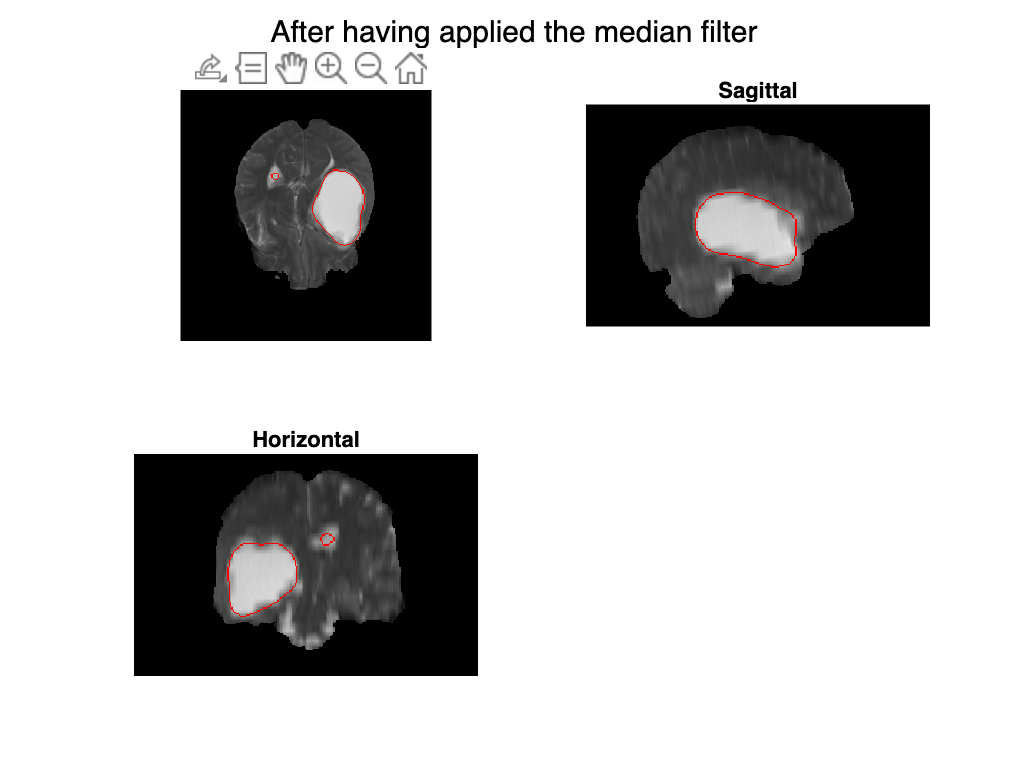

kernel = [15, 15, 15];
filteredBrain = medfilt3(binaryBrain(:, :, :), kernel);

show2Dcontours(brainMRIStrectched, filteredBrain, xMiddle, yMiddle, zMiddle);
sgtitle("After having applied the median filter")

## 7 - Results about the final segmented tumor

Ultimately, following the segmentation of the tumor, our goal is to visualize its three-dimensional volume. Additionally, we aim to extract valuable information such as the volume and dimensions of the segmented tumor for further analysis and interpretation.

volSegmented = volume(filteredBrain, 1, 1, 1);
volLabel = volume(labelMRIbinarized, 1, 1, 1);
fprintf("The volume of the segmented tumor is is %.2f cm^3", volSegmented);

The volume of the segmented tumor is is 103.97 cm^3

fprintf("The volume of the ground-truth tumor is is %.2f cm^3", volLabel);

The volume of the ground-truth tumor is is 119.72 cm^3

difVolume = volSegmented - volLabel;
fprintf('Difference between volumes: %.4f cm^3\n', difVolume);

Difference between volumes: -15.7530 cm^3



distanceTransform = bwdist(filteredBrain);
maxDistanceSegmentation = max(distanceTransform(:));
fprintf('Maximum distance between two points in the segmented image: %.4f mm\n', maxDistanceSegmentation);

Maximum distance between two points in the segmented image: 166.7813 mm



distanceTransform = bwdist(labelMRIbinarized);
maxDistanceLabel = max(distanceTransform(:));
fprintf('Maximum distance between two points in the label: %.4f mm\n', maxDistanceLabel);

Maximum distance between two points in the label: 185.3214 mm


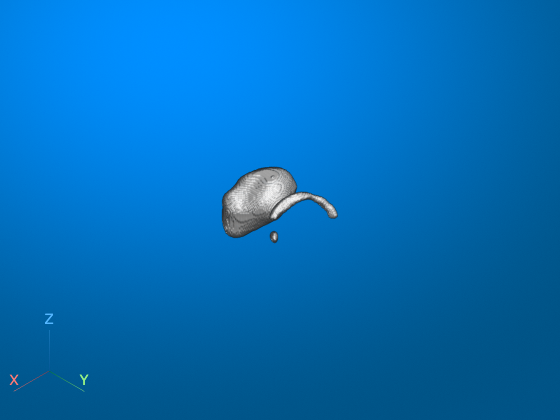



volshow(filteredBrain);

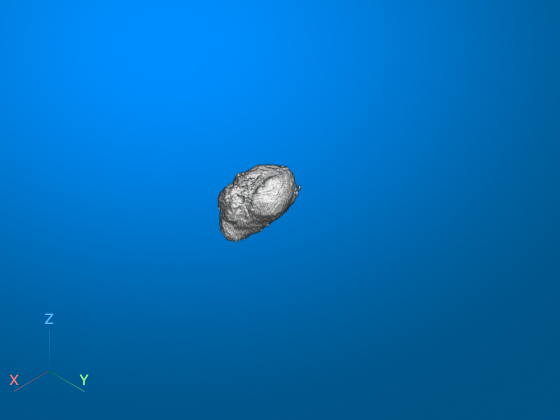

disp("")
volshow(labelMRIbinarized);

## 8 - Evaluation

In this section, our objective is to systematically assess the outcomes of this segmentation approach using the ground truth label.

intersection = sum(labelMRIbinarized(:) & filteredBrain(:));
union = sum(labelMRIbinarized(:) | filteredBrain(:));
iou = intersection / union;
fprintf('Intersection over Union (IoU) index: %.4f\n', iou);

confMatrix = confusionmat(filteredBrain(:), labelMRIbinarized(:));
figure
confusionchart(confMatrix)

truePositive = confMatrix(2, 2); 
falsePositive = confMatrix(1, 2);
falseNegative = confMatrix(2, 1);
trueNegative = confMatrix(1, 1);

accuracy = (truePositive + trueNegative) / sum(confMatrix(:));
fprintf('Accuracy score: %.4f\n', accuracy);

totalGroundTruthPixels = sum(labelMRIbinarized(:));
totalSegmentationPixels = sum(filteredBrain(:));

diceCoefficient = (2 * intersection) / (totalGroundTruthPixels + totalSegmentationPixels);
fprintf('Dice Coefficient: %.4f\n', diceCoefficient);

## 9 - Export the segmented tumor in STL format to 3D print the result

Here we export 3D data into an STL surface file, useful for 3D print the segmented tumor.

cc = bwconncomp(binaryImage);
numPixels = cellfun(@numel, cc.PixelIdxList);
[~, idx] = max(numPixels);
largestPiece = false(size(binaryImage));
largestPiece(cc.PixelIdxList{idx}) = true;
[faces, verts] = isosurface(largestPiece, 0.5);
TR = triangulation(faces, verts);
stlwrite(TR, 'tumor.stl');


cc = bwconncomp(filteredBrain);
numPixels = cellfun(@numel, cc.PixelIdxList);
[~, idx] = max(numPixels);
largestPiece = false(size(filteredBrain));
largestPiece(cc.PixelIdxList{idx}) = true;
[faces, verts] = isosurface(largestPiece, 0.5);
TR = triangulation(faces, verts);
stlwrite(TR, 'label.stl');